clc;clear;

% 打开原文件和新文件
fid_in = fopen('.\Data\data_for_doubleAOA\test-30_2.log', 'r');
fid_out = fopen('.\Data\data_for_doubleAOA\test-30_2.txt', 'w');


% 循环读取每一行
while ~feof(fid_in)
    line = fgetl(fid_in);  % 读取一行
    % 判断并删除开头的 '00>'（含空格）
    if startsWith(line, '00> ')
        line = extractAfter(line, '00> ');
    elseif startsWith(line, '00>')
        line = extractAfter(line, '00>');
    end

    % 写入新文件
    fprintf(fid_out, '%s\n', line);
end

% 关闭文件
fclose(fid_in);
fclose(fid_out);


disp('处理完成！');

处理完成！


% 读取文本文件


filename = '.\Data\data_for_doubleAOA\test-30_2.txt';  % <-- 改成你的文件名
fid = fopen(filename, 'r');

rawData = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);

% 获取行内容
lines = rawData{1};


% 初始化存储变量
sn_len = [];
% CIR存储结构

Ipatov_CIR = [];
STS0_CIR = [];
STS1_CIR = [];

% 状态标志
current_mode = '';   % 当前是哪种CIR类型（Ipatov / STS0 / STS1）
inside_CIR_block = false;  % 是否正在读取CIR数据

% 遍历每一行，按规则提取
for i = 1:length(lines)
    line = strtrim(lines{i});
    
    if contains(line, 'Sequence Number')
        tokens = regexp(line, 'Sequence Number[:\s]+(\d+)', 'tokens');
        if ~isempty(tokens)
            sn_len = [sn_len, str2double(tokens{1}{1})];
        else
            disp(['Regex failed to match: ', line]);  % 调试用
        end
    end
        
    
 % 检测 CIR 类型标志
    if contains(line, 'Printing Ipatov CIR')
        current_mode = 'Ipatov';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS0 CIR')
        current_mode = 'STS0';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS1 CIR')
        current_mode = 'STS1';
        inside_CIR_block = false;  % 等待进入“-----------”段 
    end
    
    % 检测 “-----------” 的起始和结束
    if contains(line, '_________________________________')
        inside_CIR_block = ~inside_CIR_block;  % 切换状态
        continue;  % 这行不用处理
    end
    
    % 正在 CIR 数据块内，提取 I, Q
    if inside_CIR_block
        data_tokens = regexp(line, '(-?\d+),(-?\d+)', 'tokens');
        if ~isempty(data_tokens)
            I_val = str2double(data_tokens{1}{1});
            Q_val = str2double(data_tokens{1}{2});
            complex_val = I_val + 1j * Q_val;
            % 根据当前模式放入不同数组
            if strcmp(current_mode, 'Ipatov')
                Ipatov_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS0')
                STS0_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS1')
                STS1_CIR(end+1, 1) = complex_val;
            end
        end
    end
end

% 输出到命令行确认
disp(['Sequence Number: ', num2str(sn_len)]);

Sequence Number: 143  146   22   25  157  160   36   39  171  174   50   53  185  188   64   67  199  202   78   81  213  216   92   95  227  230  106  109  241  244  120  123  255    2  134  137   13   16  148  151   27   30


packets_num = floor(length(STS0_CIR)/512);  % 向下取整，确保能reshape成功
STS0_CIR = reshape(STS0_CIR(1:512 * packets_num), 512, packets_num).';
STS1_CIR = reshape(STS1_CIR(1:512 * packets_num), 512, packets_num).';


% 如果 packets_num 是奇数，丢弃最后一行
if mod(packets_num, 2) ~= 0
    STS0_CIR(end, :) = [];



    STS1_CIR(end, :) = [];
    packets_num = packets_num - 1 ;

end

c =physconst("LightSpeed"); % wavelength (assume)
% lambda=c/4992.8e6;
lambda=c/7.9872e9;
antennaSpacing = lambda * 0.5;
% antennaSpacing = 0.0182;



% frequency=4992.8e6;
frequency=7.9872e9;
phase_offset = 0.17; %注意，在这里10.25的phase_offset还是0.17
% -0.67, -0.88, -1.01， -0.72 

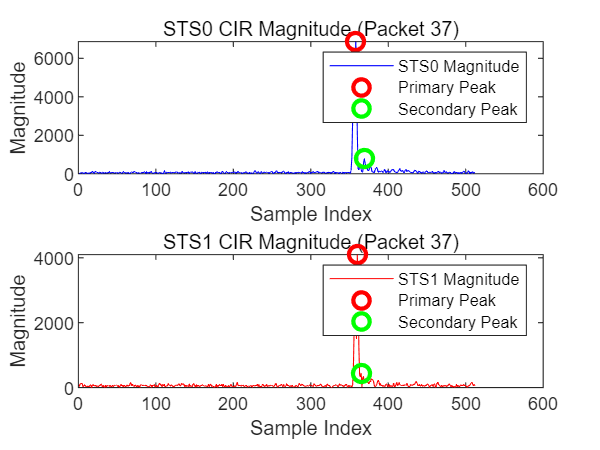

aoa_pdoa_values_main = [];
aoa_degree_values_main = [];

aoa_pdoa_values_secondary = [];
aoa_degree_values_secondary = [];

peaks_index_STS0 = [];
peaks_index_STS1 = [];



for i = 1:packets_num
    % i =2 ;

    % 取出第 i 组 CIR 数据
    STS0_data = STS0_CIR(i,:);  
    STS1_data = STS1_CIR(i,:);
    
    % 幅度
    STS0_magnitude = abs(STS0_data);
    STS1_magnitude = abs(STS1_data);


    threshold = 0.1;  % 阈值
    min_peak_distance = 4;  % 峰值之间最少间隔 4 个采样点
    
    % 找峰值
    [peaks_STS0, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_STS1, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);


    % 主峰和次强峰索引（需保证至少两个峰被找到）
    if length(locs_STS0) < 2 || length(locs_STS1) < 2
        continue; % 跳过不满足条件的帧
    end

    % 主峰和次强峰索引
    peak_index1_STS0 = locs_STS0(1);
    peak_index2_STS0 = locs_STS0(2);
    
    peak_index1_STS1 = locs_STS1(1);
    peak_index2_STS1 = locs_STS1(2);


    % 保存索引
    peaks_index_STS0 = [peaks_index_STS0; peak_index1_STS0,peak_index2_STS0];
    peaks_index_STS1 = [peaks_index_STS1; peak_index1_STS1,peak_index2_STS1];
    
    %% ---- 主峰相位差计算 ----
    STS0_phase_main = angle(STS0_data(peak_index1_STS1));
    STS1_phase_main = angle(STS1_data(peak_index1_STS1));
    phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
    phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;

    theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_main = rad2deg(theta_radians_main);

    aoa_pdoa_values_main(1,end+1) = phase_difference_main;
    aoa_degree_values_main(1,end+1) = theta_degrees_main;
    
    %% ---- 次强峰相位差计算 ----
    STS0_phase_secondary = angle(STS0_data(peak_index2_STS1));
    STS1_phase_secondary = angle(STS1_data(peak_index2_STS1));
    phase_difference_secondary = STS1_phase_secondary - STS0_phase_secondary - phase_offset;
    phase_difference_secondary = mod(phase_difference_secondary + pi, 2*pi) - pi;

    theta_radians_secondary = asin(phase_difference_secondary * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_secondary = rad2deg(theta_radians_secondary);

    aoa_pdoa_values_secondary(1,end+1) = phase_difference_secondary;
    aoa_degree_values_secondary(1,end+1) = theta_degrees_secondary;

    % ---- 画图并标记峰值 ----
    figure(100);
    clf; % 清空画布

    subplot(2,1,1);
    plot(STS0_magnitude, 'b');
    hold on;
    plot(peak_index1_STS0, STS0_magnitude(peak_index1_STS0), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    plot(peak_index2_STS0, STS0_magnitude(peak_index2_STS0), 'go', 'MarkerSize', 8, 'LineWidth', 2); % 次强峰
    hold off;
    title(['STS0 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS0 Magnitude', 'Primary Peak', 'Secondary Peak');

    subplot(2,1,2);
    plot(STS1_magnitude, 'r');
    hold on;
    plot(peak_index1_STS1, STS1_magnitude(peak_index1_STS1), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    plot(peak_index2_STS1, STS1_magnitude(peak_index2_STS1), 'go', 'MarkerSize', 8, 'LineWidth', 2); % 次强峰
    hold off;
    title(['STS1 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS1 Magnitude', 'Primary Peak', 'Secondary Peak');
    % 
    % % 把当前帧写入视频
    % frame = getframe(gcf);
    % writeVideo(v, frame);
end

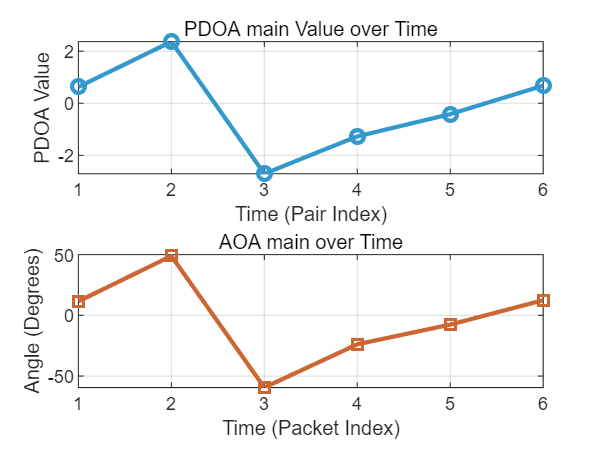

time = 1:length(aoa_pdoa_values_main);
figure;
%.\Data\角度\-45\1.txt
subplot(2,1,1);
plot(time, aoa_pdoa_values_main, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA main Value over Time');
xlabel('Time (Pair Index)');
ylabel('PDOA Value');





grid on;



subplot(2,1,2);
plot(time, aoa_degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('AOA main over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(aoa_pdoa_values_main);
mean_degree = mean(aoa_degree_values_main);

% 2. 计算标准差
std_pdoa = std(aoa_pdoa_values_main);
std_degree = std(aoa_degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: -0.12


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 1.76



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: -3.02


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 36.85


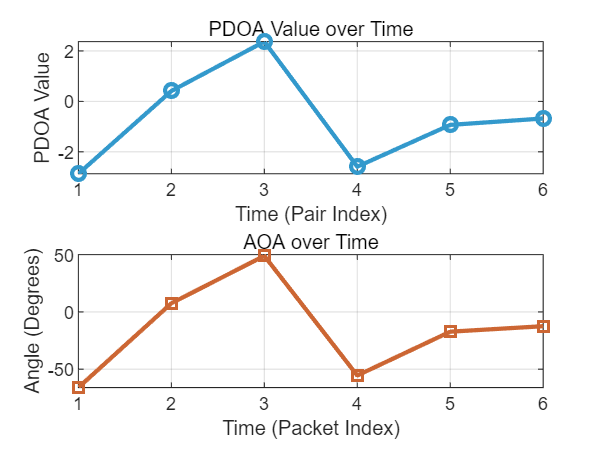


%这个数据太拉了
figure;
time = 1:length(aoa_pdoa_values_secondary);
figure;
subplot(2,1,1);
plot(time, aoa_pdoa_values_secondary, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Pair Index)');
ylabel('PDOA Value');

grid on;

subplot(2,1,2);
plot(time, aoa_degree_values_secondary, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('AOA over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;

std_pdoa_secondary= std(aoa_pdoa_values_secondary);
std_degree_secondary = std(aoa_degree_values_secondary);

mean_pdoa_secondary = mean(aoa_pdoa_values_secondary);
mean_degree_secondary= mean(aoa_degree_values_secondary);
fprintf('PDOA 平均值: %.2f\n', mean_pdoa_secondary);

PDOA 平均值: -0.72


fprintf('PDOA 标准差: %.2f\n', std_pdoa_secondary);

PDOA 标准差: 1.95



fprintf('\nDegree 平均值: %.2f\n', mean_degree_secondary);


Degree 平均值: -15.80


fprintf('Degree 标准差: %.2f\n', std_degree_secondary);

Degree 标准差: 42.07



%这组数据可以记录为(37.24,-0.01)lt,离开角朝向为45°，右侧为(43.8,2.92)
%在.\Data\角度\45这个地方，最终测量的角度是 (41.86,29.91)

%这段代码是对pdoa进行筛选
threshold = 2;

% 筛选主数据
valid_idx_main = abs(aoa_pdoa_values_main - mean_pdoa) <= threshold * std_pdoa & ...
                abs(aoa_degree_values_main - mean_degree) <= threshold * std_degree;

% 筛选副数据
valid_idx_secondary = abs(aoa_pdoa_values_secondary - mean_pdoa_secondary) <= threshold * std_pdoa_secondary & ...
                     abs(aoa_degree_values_secondary - mean_degree_secondary) <= threshold * std_degree_secondary;

% 获取有效数据
filtered_pdoa_main = aoa_pdoa_values_main(valid_idx_main);
filtered_degree_main = aoa_degree_values_main(valid_idx_main);

filtered_pdoa_secondary = aoa_pdoa_values_secondary(valid_idx_secondary);
filtered_degree_secondary = aoa_degree_values_secondary(valid_idx_secondary);

% 显示筛选结果
fprintf('主数据筛选结果:\n');

主数据筛选结果:


fprintf('原始数据量: %d, 筛选后数据量: %d, 保留比例: %.2f%%\n', ...
        length(aoa_pdoa_values_main), length(filtered_pdoa_main), ...
        length(filtered_pdoa_main)/length(aoa_pdoa_values_main)*100);

原始数据量: 32, 筛选后数据量: 32, 保留比例: 100.00%



fprintf('副数据筛选结果:\n');

副数据筛选结果:


fprintf('原始数据量: %d, 筛选后数据量: %d, 保留比例: %.2f%%\n', ...
        length(aoa_pdoa_values_secondary), length(filtered_pdoa_secondary), ...
        length(filtered_pdoa_secondary)/length(aoa_pdoa_values_secondary)*100);

原始数据量: 32, 筛选后数据量: 32, 保留比例: 100.00%



% 计算筛选后的统计量
if ~isempty(filtered_pdoa_main)
    filtered_mean_pdoa_main = mean(filtered_pdoa_main);
    filtered_std_pdoa_main = std(filtered_pdoa_main);
    filtered_mean_degree_main = mean(filtered_degree_main);
    filtered_std_degree_main = std(filtered_degree_main);
    
    fprintf('\n筛选后主数据统计:\n');
    fprintf('PDOA 平均值: %.2f, 标准差: %.2f\n', filtered_mean_pdoa_main, filtered_std_pdoa_main);
    fprintf('Degree 平均值: %.2f, 标准差: %.2f\n', filtered_mean_degree_main, filtered_std_degree_main);
end


筛选后主数据统计:


PDOA 平均值: -0.51, 标准差: 0.22


Degree 平均值: -9.42, 标准差: 4.02



if ~isempty(filtered_pdoa_secondary)
    filtered_mean_pdoa_secondary = mean(filtered_pdoa_secondary);
    filtered_std_pdoa_secondary = std(filtered_pdoa_secondary);
    filtered_mean_degree_secondary = mean(filtered_degree_secondary);
    filtered_std_degree_secondary = std(filtered_degree_secondary);
    
    fprintf('\n筛选后副数据统计:\n');
    fprintf('PDOA 平均值: %.2f, 标准差: %.2f\n', filtered_mean_pdoa_secondary, filtered_std_pdoa_secondary);
    fprintf('Degree 平均值: %.2f, 标准差: %.2f\n', filtered_mean_degree_secondary, filtered_std_degree_secondary);
end


筛选后副数据统计:


PDOA 平均值: 1.41, 标准差: 0.16


Degree 平均值: 26.77, 标准差: 3.17



% 绘制筛选后的数据对比图
figure;

% 主数据筛选前后对比
subplot(2,2,1);
hold on;
plot(time, aoa_pdoa_values_main, 'o-', 'LineWidth', 1, 'Color', [0.7 0.7 0.7], 'MarkerSize', 3);
plot(time(valid_idx_main), filtered_pdoa_main, 'o-', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('主数据PDOA筛选前后对比');
xlabel('时间 (数据包索引)');
ylabel('PDOA值');
legend('原始数据', '筛选后数据', 'Location', 'best');
grid on;

subplot(2,2,2);
hold on;
plot(time, aoa_degree_values_main, 's-', 'LineWidth', 1, 'Color', [0.7 0.7 0.7], 'MarkerSize', 3);
plot(time(valid_idx_main), filtered_degree_main, 's-', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('主数据AOA筛选前后对比');
xlabel('时间 (数据包索引)');
ylabel('角度 (度)');
legend('原始数据', '筛选后数据', 'Location', 'best');
grid on;

% 副数据筛选前后对比
time_secondary = 1:length(aoa_pdoa_values_secondary);
subplot(2,2,3);
hold on;
plot(time_secondary, aoa_pdoa_values_secondary, 'o-', 'LineWidth', 1, 'Color', [0.7 0.7 0.7], 'MarkerSize', 3);
plot(time_secondary(valid_idx_secondary), filtered_pdoa_secondary, 'o-', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('副数据PDOA筛选前后对比');
xlabel('时间 (数据包索引)');
ylabel('PDOA值');
legend('原始数据', '筛选后数据', 'Location', 'best');
grid on;

subplot(2,2,4);
hold on;
plot(time_secondary, aoa_degree_values_secondary, 's-', 'LineWidth', 1, 'Color', [0.7 0.7 0.7], 'MarkerSize', 3);
plot(time_secondary(valid_idx_secondary), filtered_degree_secondary, 's-', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('副数据AOA筛选前后对比');
xlabel('时间 (数据包索引)');
ylabel('角度 (度)');
legend('原始数据', '筛选后数据', 'Location', 'best');
grid on;


% 记录最终测量结果
fprintf('\n=== 最终测量结果 ===\n');


=== 最终测量结果 ===


if ~isempty(filtered_pdoa_main)
    fprintf('主数据最终测量: (%.2f, %.2f)\n', filtered_mean_degree_main, filtered_mean_pdoa_main);
end

主数据最终测量: (-9.42, -0.51)


if ~isempty(filtered_pdoa_secondary)
    fprintf('副数据最终测量: (%.2f, %.2f)\n', filtered_mean_degree_secondary, filtered_mean_pdoa_secondary);
end

副数据最终测量: (26.77, 1.41)



%receivelt2 main:-35.14 secondary:0.02
%receivert2 main:44.49 secondary: 3.77
%receivelt1 main:
%receivert4 main:41.85 -0.40 secondary: -19.17 18.17(why?)

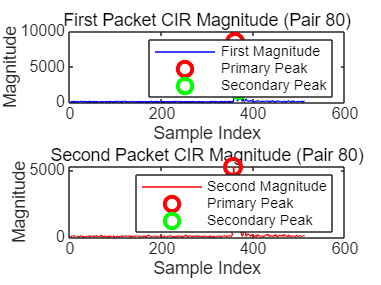

first_packet_cir  = STS0_CIR(1:2:end, :);  % 奇数行
second_packet_cir = STS0_CIR(2:2:end, :);  % 偶数行

aod_pdoa_values_main = [];
aod_degree_values_main = [];

aod_pdoa_values_secondary = [];
aod_degree_values_secondary = [];

peaks_index_first = [];
peaks_index_second = [];

% video_filename = 'AOD_3.avi';
% v = VideoWriter(video_filename);  % 默认是 Motion JPEG AVI
% v.FrameRate = 5;  % 可根据需要调整帧率
% open(v);

num_pairs = size(first_packet_cir, 1);  % 每组两个packet

for i = 1:num_pairs
    first_data = first_packet_cir(i, :);
    second_data = second_packet_cir(i, :);
    
    % 幅度
    first_magnitude = abs(first_data);
    second_magnitude = abs(second_data);

    threshold = 0.1;
    min_peak_distance = 4;
    
    [peaks_first, locs_first] = findpeaks(first_magnitude, 'MinPeakHeight', threshold * max(first_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_second, locs_second] = findpeaks(second_magnitude, 'MinPeakHeight', threshold * max(second_magnitude), 'MinPeakDistance', min_peak_distance);

    % 主峰和次强峰索引（需保证至少两个峰被找到）
    if length(locs_first) < 2 || length(locs_second) < 2
        continue; % 跳过不满足条件的帧
    end

    peak_index1_first = locs_first(1);
    peak_index2_first = locs_first(2);

    peak_index1_second = locs_second(1);
    peak_index2_second = locs_second(2);

   
    peaks_index_first = [peaks_index_first; peak_index1_first, peak_index2_first];
    peaks_index_second = [peaks_index_second; peak_index1_second, peak_index2_second];

    % ---- 主峰相位差计算 ----
    phase_first_main = angle(first_data(peak_index1_second));
    phase_second_main = angle(second_data(peak_index1_second));
    phase_diff_main = phase_second_main - phase_first_main ;
    phase_diff_main = mod(phase_diff_main + pi, 2*pi) - pi;

    theta_rad_main = asin(phase_diff_main * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_main = rad2deg(theta_rad_main);

    aod_pdoa_values_main(end+1) = phase_diff_main;
    aod_degree_values_main(end+1) = theta_deg_main;

    % ---- 次强峰相位差计算 ----
    phase_first_sec = angle(first_data(peak_index2_second));
    phase_second_sec = angle(second_data(peak_index2_second));
    phase_diff_sec = phase_second_sec - phase_first_sec;
    phase_diff_sec = mod(phase_diff_sec + pi, 2*pi) - pi;

    theta_rad_sec = asin(phase_diff_sec * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_sec = rad2deg(theta_rad_sec);

    aod_pdoa_values_secondary(end+1) = phase_diff_sec;
    aod_degree_values_secondary(end+1) = theta_deg_sec;

    % ---- 画图 ----
    figure(100);    
    clf; 
    subplot(2,1,1);
    plot(first_magnitude, 'b');
    hold on;
    plot(peak_index1_first, first_magnitude(peak_index1_first), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index2_first, first_magnitude(peak_index2_first), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    title(['First Packet CIR Magnitude (Pair ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('First Magnitude', 'Primary Peak', 'Secondary Peak');

    subplot(2,1,2);
    plot(second_magnitude, 'r');
    hold on;
    plot(peak_index1_second, second_magnitude(peak_index1_second), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index2_second, second_magnitude(peak_index2_second), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    title(['Second Packet CIR Magnitude (Pair ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('Second Magnitude', 'Primary Peak', 'Secondary Peak');

    % frame = getframe(gcf);
    % writeVideo(v, frame);
end


% close(v);
% disp(['视频已保存为: ', video_filename]);

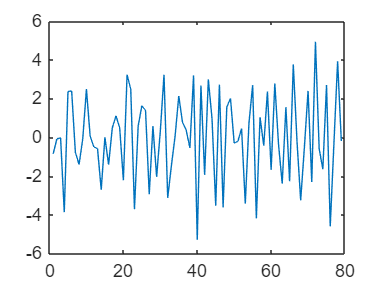

figure;
pd = diff(aod_pdoa_values_main);
plot(pd)

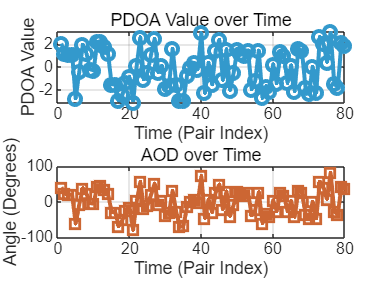

time = 1:length(aod_pdoa_values_main);
figure;
subplot(2,1,1);
plot(time, aod_pdoa_values_main, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Pair Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, aod_degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('AOD over Time');
xlabel('Time (Pair Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(aod_pdoa_values_main);
mean_degree = mean(aod_degree_values_main);

% 2. 计算标准差
std_pdoa = std(aod_pdoa_values_main);
std_degree = std(aod_degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: -0.07


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 1.74



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: -1.73


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 36.89
